## Unipolar Square Wave

Written by Dr. Azemi Can at the University of Pittsburgh for ECE 0402

Let x(t) be periodic with fundamental period T where: 


$$x\left(t\right)-\left\lbrace \begin{array}{ll}
1 & -T_1 <t<T_1 \\
0 & -\frac{T}{2}<t<T_1 ,T_1 <t<\frac{T}{2}
\end{array}\right.$$


If we choose to integrate over $-\frac{T}{2}\le t\le \frac{T}{2}$, then we get:


$$X_0 =\frac{1}{T}\int_{-T_1 }^{T_1 } \textrm{dt}=2\frac{T_1 }{T}$$



$$X_k =\frac{1}{T}\int_{-\frac{T_1 }{2}}^{\frac{T_1 }{2}} x\left(t\right)e^{-\textrm{jk}\omega_0 t} \textrm{dt}=2\frac{T_1 }{T}\cdot \frac{\sin \left(2\pi \;\frac{{\textrm{kT}}_t }{T}\right)}{2\pi \;\frac{{\textrm{kT}}_1 }{T}}$$


Where $\alpha =2\frac{T_1 }{T}$ is the duty cycle.

First, define the parameters. 

clear;
clc;

T = 1; % fundamental period
t_max = 2.5*T; % axis limits
t_min = -t_max; % axis limits
dt = T/1000; % time steps
t = t_min : dt : t_max; % time array
x = zeros(size(t)); % empty array to store coefficients


Next, set up the structure of the graph in the time domain

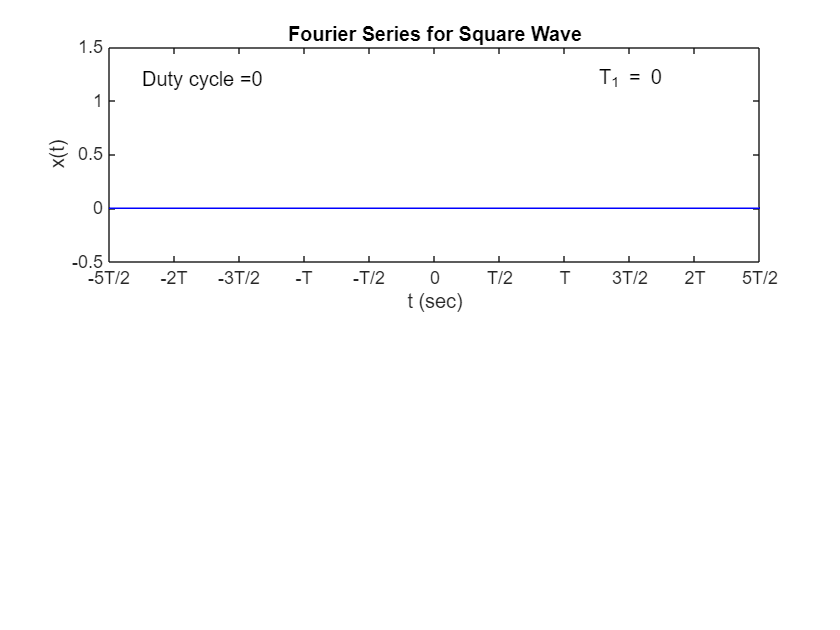

figure(1);
clf;
subplot(2,1,1);
h1 = plot(t,x,'b');
axis([t_min t_max -0.5 1.5]);
h2 = text(0.9*t_min, 1.2,['Duty cycle =0']);
h3 = text(0.5*t_max,1.2,['T_1 = 0']);
xlabel('t (sec)');
ylabel('x(t)');
title('Fourier Series for Square Wave');
% set the property values of the current graph
set(gca,'XTick',[-2.5*T: 0.5*T : 2.5*T]);
set(gca,'XTickLabel',{'-5T/2','-2T','-3T/2','-T','-T/2','0','T/2','T','3T/2','2T','5T/2'})

Next, Set up the parameters for the Fourier Coefficient graph

k_max = 30; % max for harmonics
k_min = -k_max; % min for harmonics
k = k_min: k_max; % -30:1:30
X = zeros(size(k)); % open array to store Fourier coefficients

w = k_min : 0.1 : k_max; % -30:0.1:30
X2 = zeros(size(w)); % open array to store Fourier coefficients

Next, set up the structure of the graph in the time domain

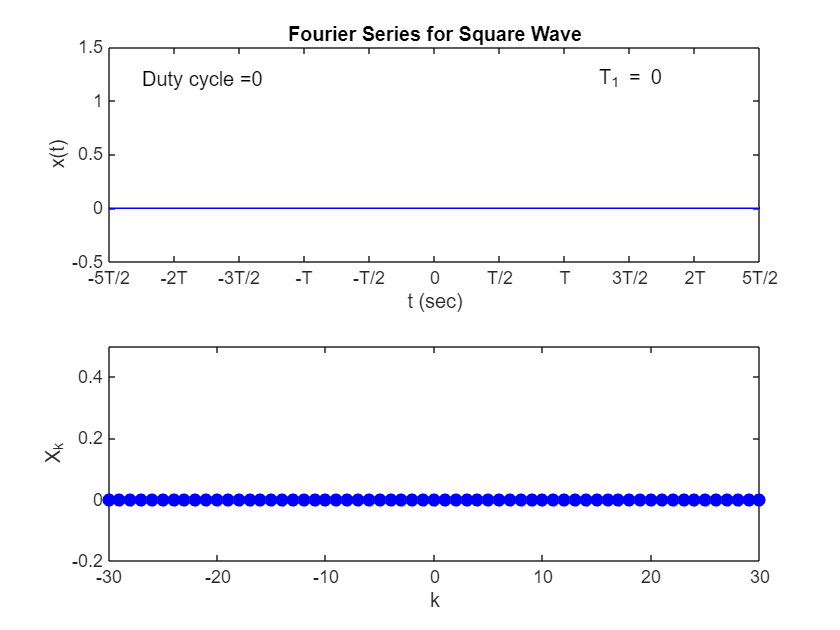

subplot(2,1,2);
h4 = stem(k,X,'b','filled'); % plot discrete sequence data
xlabel('k');
ylabel('X_k');
axis([k_min k_max -0.2 0.5]);
hold on;
h5 = plot(w,X2,'b--');
hold off;

Compute the fourier coefficients for each duty cycle from 0.05 to 0.95 

for duty_cycle = 0.05: 0.05: 0.95
    T_1 = duty_cycle * T/2; % determine how long squre wave is high
    x(1:end) = 0; % clear array x for each loop
    for i = -2 : 2
        % t is in the range of -2.5*T to 2.5*T.
        subset = (abs(t-i*T) < T_1); % detemine where to set square wave high.
        x(subset) = 1; % set the value high for the subset.
    end

    set(h1, "YData",x); % update the square wave
    set(h2, 'String',['Duty cycle =' num2str(duty_cycle)]);
    set(h3, 'String',['T_1 =' num2str(T_1/T) 'T']);

    X = duty_cycle * sinc(k*duty_cycle);
    X2 = duty_cycle * sinc(w * duty_cycle);
    set(h4,'YData',X); % update the Fourier coefficients
    set(h5,'YData',X2); % update the Fourier coefficients

    waitforbuttonpress;

end 

Error using waitforbuttonpress
waitforbuttonpress exit because target figure has been deleted